`（1）分别求出``的系统响应，并画出其波形`

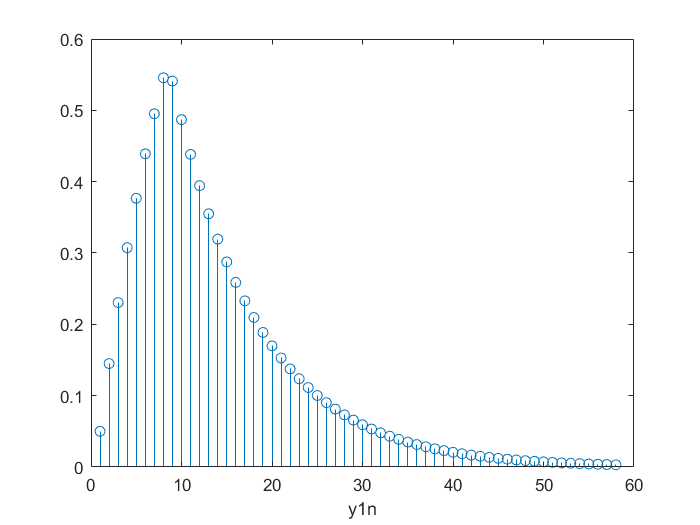

%================(1)=================
A=[1,-0.9];B=[0.05,0.05];  %系统差分方程系数
x1n=[1 1 1 1 1 1 1 1 zeros(1,50)];  %产生信号x1(n)=R8(n)
x2n=ones(1,100);    %产生信号x2(n)=u(n)

y1n=filter(B,A,x1n);    %求响应y1(n)
y2n=filter(B,A,x2n);    %求响应y2(n)
n1 = 0 : length(y1nn)-1;
stem(y1n);
xlabel("y1n");

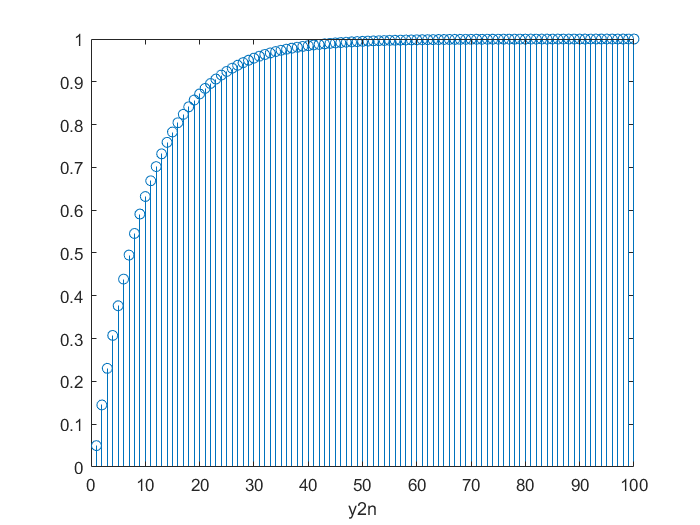

n2 = 0 : length(y2n)-1;
stem(y2n);
xlabel("y2n");

(2)`求出系统的单位脉冲响应，画出其波形`

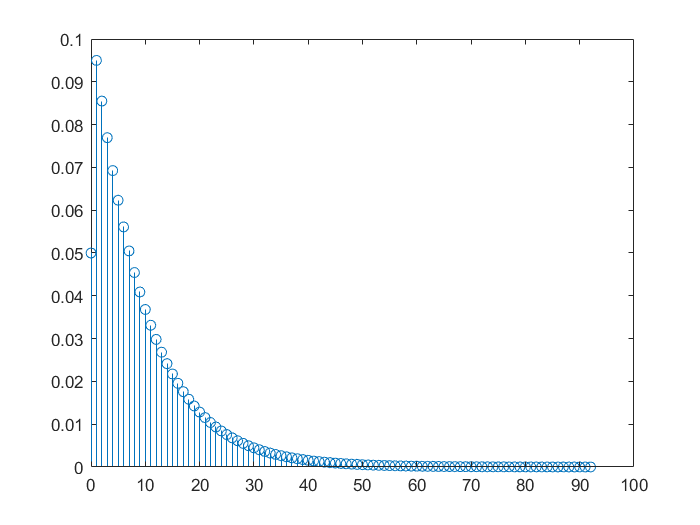

hn=impz(B,A);    %求系统单位脉冲响应h(n)
nh = 0:length(hn) -1;
stem(nh,hn)